% Parámetros
Kt = 0.44; % Constante de torque (N·m/A)
R = 2.5; % Resistencia (Ohms)
J = 18.38e-6; % Momento de inercia total (kg·m^2)
B = 1e-3; % Coeficiente de fricción viscosa (N·m·s)

% Transferencia
numerador = Kt / R;
denominador = [J, B, 0];
sys = tf(numerador, denominador)

sys =
 
           0.176
  -----------------------
  1.838e-05 s^2 + 0.001 s
 
Continuous-time transfer function.
Model Properties




% Mostrar la función de transferencia
disp('Función de transferencia del sistema:')

Función de transferencia del sistema:


disp(sys);

  tf with properties:

       Numerator: {[0 0 0.1760]}
     Denominator: {[1.8380e-05 1.0000e-03 0]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



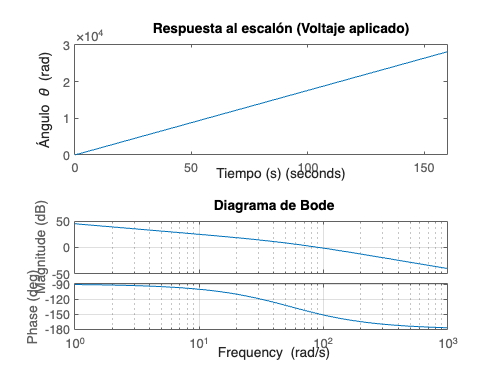


% Análisis en MATLAB
figure;
% Respuesta al escalón (voltaje constante aplicado)
subplot(2,1,1);
step(sys);
title('Respuesta al escalón (Voltaje aplicado)');
xlabel('Tiempo (s)');
ylabel('Ángulo \theta (rad)');

% Respuesta en frecuencia (Bode plot)
subplot(2,1,2);
bode(sys);
title('Diagrama de Bode');
grid on;

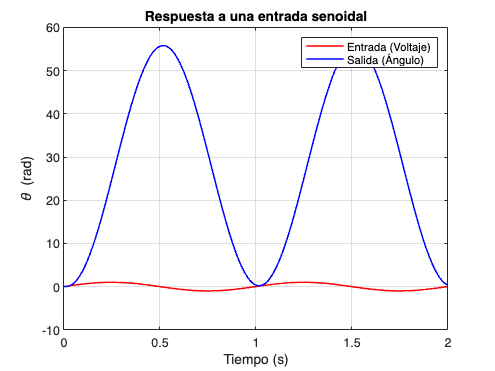


% Análisis de respuesta transitoria a una entrada senoidal
t = 0:0.01:2; % Tiempo de simulación (0 a 2 segundos)
v_input = sin(2*pi*1*t); % Entrada senoidal de 1 Hz
[y, t_out] = lsim(sys, v_input, t);

% Gráfico de la respuesta a entrada senoidal
figure;
plot(t_out, v_input, 'r', 'LineWidth', 1.2); hold on;
plot(t_out, y, 'b', 'LineWidth', 1.2);
title('Respuesta a una entrada senoidal');
xlabel('Tiempo (s)');
ylabel('\theta (rad)');
legend('Entrada (Voltaje)', 'Salida (Ángulo)');
grid on;

polos = pole(sys);
disp(polos);

         0
  -54.4070



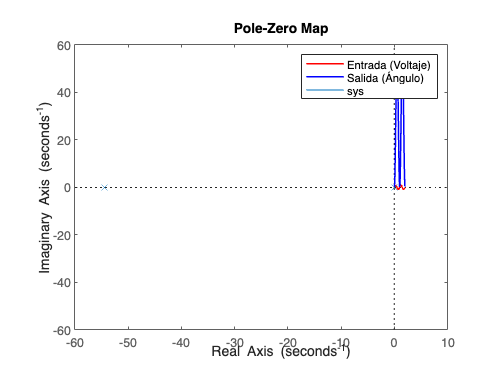

pzmap(sys);

% Parámetros del sistema
m = 0.006; % Masa de la pelota (kg)
g = 9.81; % Gravedad (m/s^2)
R = 0.02; % Radio de la pelota (m)
L = 0.36; % Longitud del brazo (m)
d = 0.027; % Distancia eje de giro al brazo (m)
J = (2/5) * m * R^2; % Momento de inercia de la pelota

% Variable de Laplace
s = tf('s');

% Función de transferencia
P_ball = -(m*g*d/L)/(J/R^2+m)/s^2

% Mostrar la función de transferencia
disp('Función de transferencia P_ball (R(s)/Theta(s)):');

Función de transferencia P_ball (R(s)/Theta(s)):


disp(P_ball);

  tf with properties:

       Numerator: {[0 0 -0.5255]}
     Denominator: {[1 0 0]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



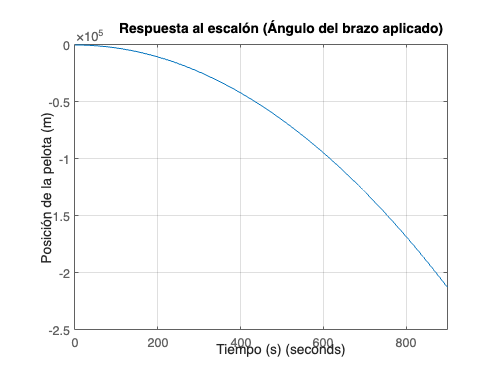


% Respuesta al escalón (para ver el comportamiento de la posición)
figure;
step(P_ball);
title('Respuesta al escalón (Ángulo del brazo aplicado)');
xlabel('Tiempo (s)');
ylabel('Posición de la pelota (m)');
grid on;

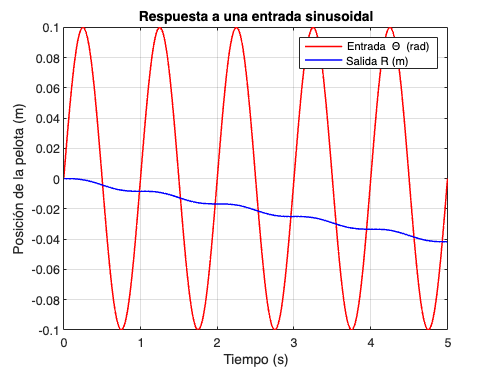


% Respuesta a una entrada sinusoidal
t = 0:0.01:5; % Tiempo (5 segundos)
theta_input = 0.1 * sin(2 * pi * 1 * t); % Ángulo sinusoidal de 1 Hz con amplitud 0.1 rad
[y, t_out] = lsim(P_ball, theta_input, t);

% Gráfico de la entrada sinusoidal y la respuesta
figure;
plot(t_out, theta_input, 'r', 'LineWidth', 1.2); hold on;
plot(t_out, y, 'b', 'LineWidth', 1.2);
title('Respuesta a una entrada sinusoidal');
xlabel('Tiempo (s)');
ylabel('Posición de la pelota (m)');
legend('Entrada \Theta (rad)', 'Salida R (m)');
grid on;